%常微分方程
clear;clc

%作业1
y=0:-0.1:-100;
for i=0:1:1000
    x(:,i+1)=xiaochuanguohe(-i/10);
end
plot(x,y);

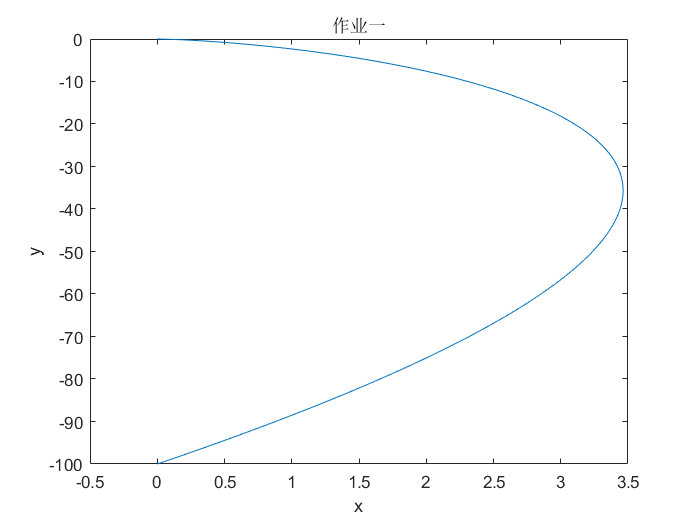

title("作业一");
xlabel("x");
ylabel("y");

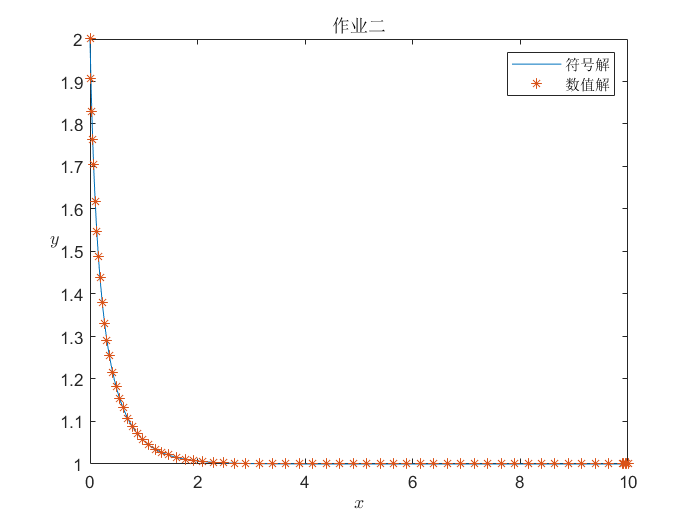

%作业2
clc, clear
syms y(x);
y=dsolve(diff(y)==y*(1-y^2), y(0)==2);
fplot(y,[0,10]);
hold on
dy=@(x,y)y*(1-y^2);
[sx, sy]=ode45(dy, [0,10], 2);
plot(sx, sy, '*'); legend({'符号解','数值解'})
title("作业二");
xlabel('$x$','Interpreter','Latex')
ylabel('$y$','Interpreter','Latex','Rotation',0)
hold off

syms x y f      % 定义微分方程
f(x,y) = cos(x).*y.^2;

a = 1;          % 定义求解区间
b = 8;
y0 = 3;         % 初值
h = 0.3;        % 步长

function [x,y] = euler(f,span,y0,h)
% 欧拉法
% f: 右端函数
% span: 求解区间
% y0: 初值
% h: 求解步长
x = [span(1):h:span(end)];
y = x*0;
y(1) = y0;
for i = 1:length(x)-1
    K1 = f(x(i),y(i));
    y(i+1) = y(i) + h*K1;
end
end
function x=xiaochuanguohe(y)
k=0.3;
x=1/2*(-0.01).^(-k).*y.^(-k+1)-1/2.*(-0.01).^k.*y.^(k+1);
end
function tu_rk
syms x y f      % 定义微分方程
f(x,y) = cos(x).*y.^2;

% 求微分方程的解析解，如有
% ————————————————————————————————————
syms y(x)
eqn = diff(y,x) == cos(x).*y.^2;
cond = y(1) == 3;
ySol(x) = dsolve(eqn,cond);

% 定义微分方程数值求解的参数
% ————————————————————————————————————
a = 1;          % 定义求解区间
b = 8;
delta = 0.2;    % 方向场离散化参数
y0 = 3;         % 初值
h = 0.3;        % 步长

% 绘制右端函数的方向场
% ————————————————————————————————————
figure('Color','k','Units','normalized','Position',[0.1 0.1 0.8 0.8])
[x,y] = meshgrid(0:delta:10,0:delta:12); %定义域
u = x*0+1;  % 全1
v = f(x,y); % f(x,y)
lamda = 0.5; % 方向场箭头的长度
dist = (u.^2+v.^2).^0.5;
u = u./dist*lamda;
v = v./dist*lamda;
quiver(x,y,u,v,'Color',[1 1 0]/1.5,'LineStyle', '-','MaxHeadSize',0.1) % 绘制方向场
hold on

% 数值求解微分方程
% ————————————————————————————————————
[x,y] = rk4(f,[a b],y0,h);

% 绘制微分方程的积分曲线
% ————————————————————————————————————
xx = [x(1):0.001:x(end)];
L = plot(xx,ySol(xx),'LineWidth',2,'Color','b');
L.Parent.Color = 'none';
axis equal
axis([0 10 0 6])
axis off
pause(0.5)

for i = 1:length(x)-1
    scatter(x(i),y(i),'MarkerFaceColor','y','MarkerEdgeColor','m','SizeData',200)
    pause(0.1)

    K1 = f(x(i),y(i));
    quiver(x(i),y(i),1/norm([1,K1])*h*7,K1/norm([1,K1])*h*7,'Color','w','LineStyle', '-','MaxHeadSize',0.05)
    pause(0.2)

    plot([x(i) x(i+1)],[y(i) y(i+1)],'LineWidth',4,'Color','y')
    pause(0.1)

end
scatter(x(end),y(end),'MarkerFaceColor','y','MarkerEdgeColor','w','SizeData',200)

end